# Microgirds 1

Yen-Chun Chen

934559635

clc
close all   % close figure windows
clear
format compact

## Run initialization

hw_microgrids1_init;


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

## Question 1

#### The starting system is only energy storage and load (the wind turbine is commented out).  The system is stable -- meaning delta_wpu is kept within +/- 0.10 -- but the starting energy storage power and energy capacity are way oversized. 

#### Use the smallest es.P_pe_rated and es.E_rated_kWh that works well (e.g., keeps delta_wpu within +/- 0.10) plus a 10% margin of safety in the power and energy capacity (i.e., make the power and energy capacity 10% larger than the bare minimum).  

To find the smallest es.P_pe_rated and es.E_rated_kWh that works well, I first gradually reduce es.E_rated_kWh from the original setting 24,000 kWh and rerun the simulation.

For each values, I check the simulation result:

- $\Delta \omega_{\textrm{pu}}$ stay within +/- 0.10

- SOC remain within -0.01 to 1.01 (due to the Relay setting)

- p_es has no larger oscillation

The value of 4,145 kWh is the smallest required energy capacity I got to meet my checklist and let the system operate stably, as shown in Figure 1.

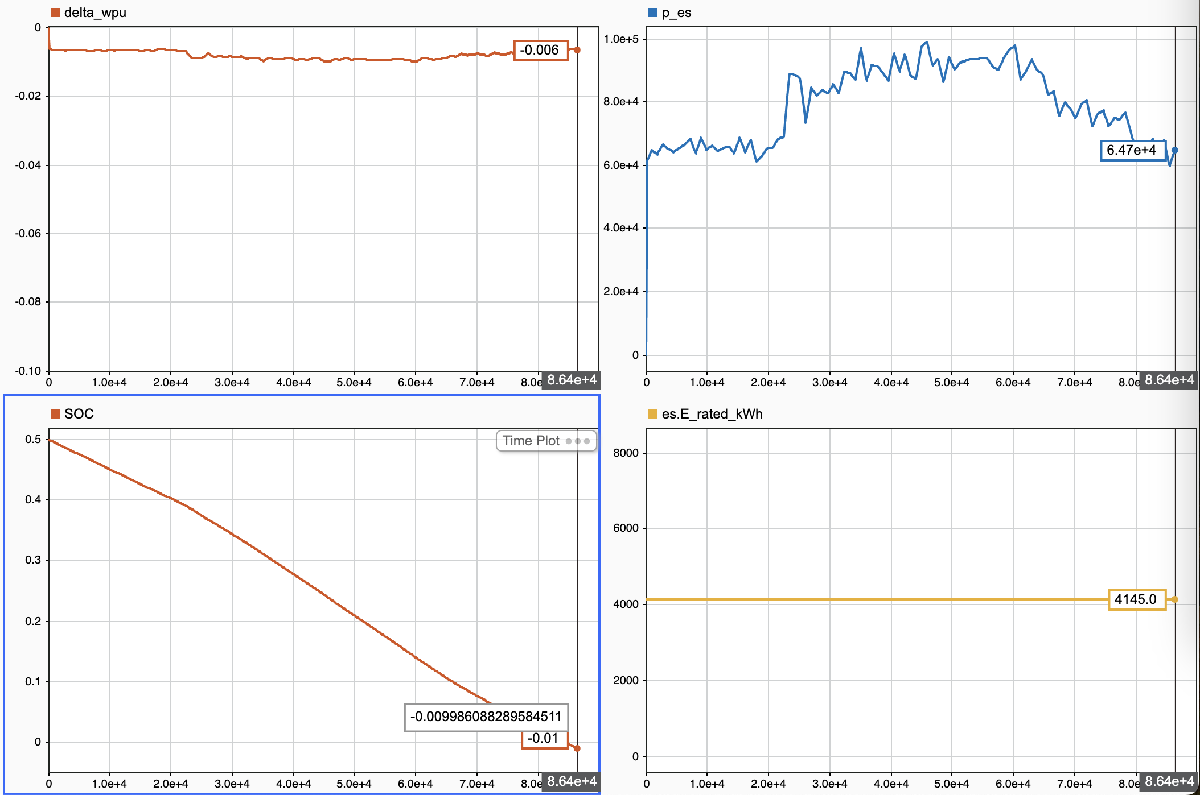

*Figure 1. The smallest es.E_rated_kWh is 4,145 kWh when only the Energy Storage system is enable.*

es.E_rated_kWh = 4145;
fprintf("The smallest required energy capacity: %.2f kWh", es.E_rated_kWh)

The smallest required energy capacity: 4145.00 kWh

Finally, apply the safety margin to es.E_rated_kWh. We got the smallest es.E_rated_kWh = 4,559.5 kWh.

es.E_rated_kWh = es.E_rated_kWh*1.1;
fprintf("The smallest es.E_rated_kWh: %.2f kWh", es.E_rated_kWh)

The smallest es.E_rated_kWh: 4559.50 kWh

The peak power of the load demand is 100 kW. Then, the required es.P_pe_rated should be adjusted for efficiency loss.

es.P_pe_rated = maxLoadPower/es.eta_pe;
fprintf("The es.P_pe_rated before efficiency loss: %.2d kW", es.P_pe_rated/1000)

The es.P_pe_rated before efficiency loss: 1.05e+02 kW

Finally, apply the safety margin to es.P_pe_rated. We got the smallest es.P_pe_rated = 116 kW.

es.P_pe_rated = es.P_pe_rated*1.1;
fprintf("The smallest es.P_pe_rated: %.2d kW", es.P_pe_rated/1000)

The smallest es.P_pe_rated: 1.16e+02 kW

#### Plot {p_ld, p_es} and SOC and delta_wpu and show what es.P_pe_rated, and es.E_rated_kWh you used.  

#### 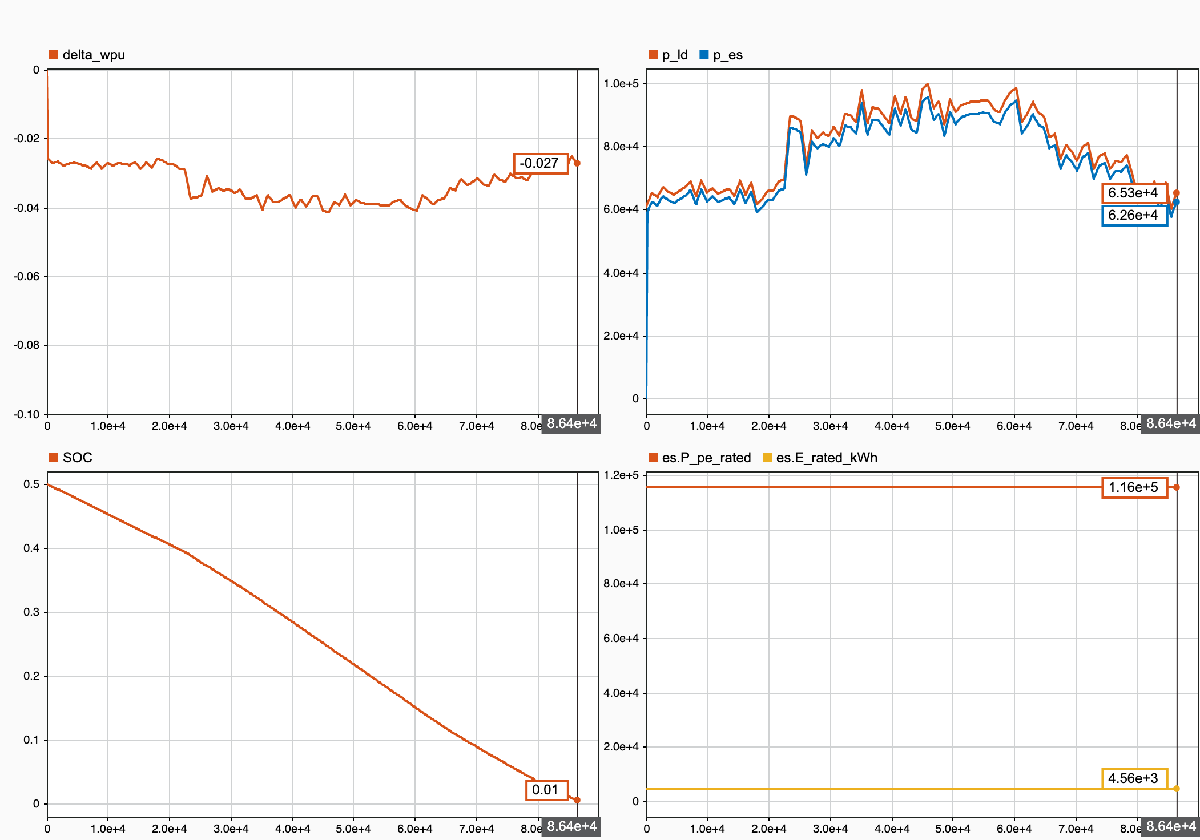

#### Using an estimate of $100 per kW of power capacity, and $130 per kWh of energy capacity, how much does your energy storage cost?  (Start with SOC = 0.5.)

energyStorageCost_power = energyStorageCost_dollarsperkW*es.P_pe_rated/1000;
fprintf("The cost of power: $%3.0f", energyStorageCost_power)

The cost of power: $11579

energyStorageCost_energy = energyStorageCost_dollarsperkWh*es.E_rated_kWh;
fprintf("The cost of energy: $%3.0f", energyStorageCost_energy)

The cost of energy: $592735

fprintf("Total cost of energy storage system: $%3.0f", energyStorageCost_power + energyStorageCost_energy)

Total cost of energy storage system: $604314

## Question 2

#### Now add the wind turbine.  What is now the smallest energy storage es.P_pe_rated and es.E_rated you can safely use?  

In theory, if we add the wind turbine power, the es.P_pe_rated and es.E_rated_kWh can be smaller than the derivation from Question 1. Therefore, I started the es.E_rated_kWh from the value of 1500 and gradually reduced it to find the smallest value that still makes the system stable. 

Similarly, the value of 1,365 kWh is the smallest required energy capacity I got to meet my checklist and let the system operate stably, as shown in Figure 2. 

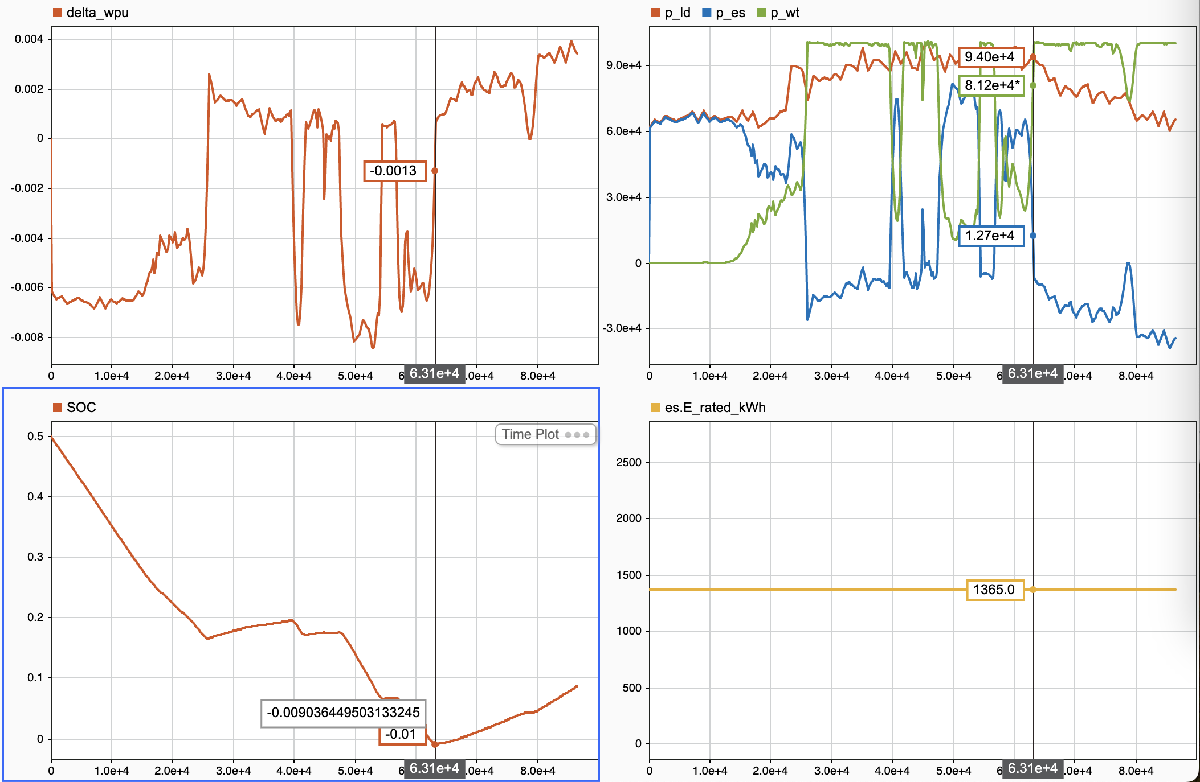

*Figure 2. The smallest es.E_rated_kWh is 1,365 kWh when both Energy Storage and Wind Turbine are enable.*

es.E_rated_kWh = 1365;
fprintf("The smallest required storage energy: %.2f kWh", es.E_rated_kWh)

The smallest required storage energy: 1365.00 kWh

Finally, apply the safety margin to es.E_rated_kWh. We got the smallest es.E_rated_kWh = 1,501.5 kWh.

es.E_rated_kWh = es.E_rated_kWh*1.1;
fprintf("The smallest es.E_rated_kWh: %.2f kWh", es.E_rated_kWh)

The smallest es.E_rated_kWh: 1501.50 kWh

The peak power of the load demand is not 100 kW due to the wind turbine system.

log = sim("hw_microgrids1_both").logsout;
p_es = log.getElement("p_es").Values.Data;
maxLoadPower_with_tb = max(p_es);
fprintf("The max required with turbine power: %.2d kW", maxLoadPower_with_tb/1000) % 8.19e+01 kW

The max required with turbine power: 8.19e+01 kW

Then, the required es.P_pe_rated should be adjusted for efficiency loss.

es.P_pe_rated = maxLoadPower_with_tb/es.eta_pe;
fprintf("The es.P_pe_rated before efficiency loss: %.2d kW", es.P_pe_rated/1000) % 8.63e+01 kW

The es.P_pe_rated before efficiency loss: 8.63e+01 kW

Finally, apply the safety margin to es.P_pe_rated. We got the smallest es.P_pe_rated = 94.9 kW.

es.P_pe_rated = es.P_pe_rated*1.1;
fprintf("The smallest es.P_pe_rated: %.2d kW", es.P_pe_rated/1000) % 9.49e+01 kW

The smallest es.P_pe_rated: 9.49e+01 kW

#### Plot {p_ld, p_es, p_wt} and SOC and delta_wpu and show what es.P_pe_rated, and es.E_rated_kWh you used.

#### 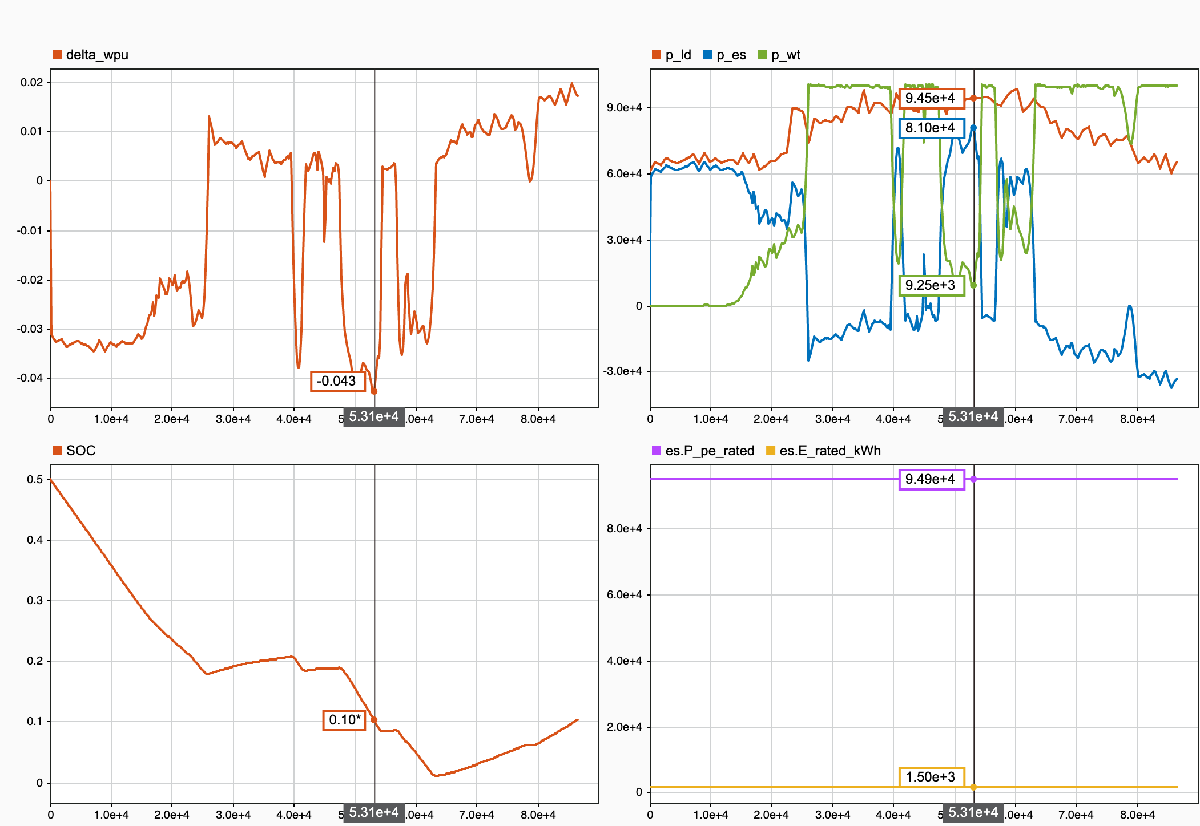

#### Why is the energy storage smaller than what you found initially?  

First of all, the initial energy storage power and energy capacity are way oversized. Secondly, the simulation revealed the actual energy we need. In addition, the renewable energy source (wind turbine power) is involved in reducing the reliance on energy storage. Thus, it makes sense that the energy storage is smaller than what I found initially.

#### How much does it cost now?  (Start with SOC=0.5.)

energyStorageCost_power = energyStorageCost_dollarsperkW*es.P_pe_rated/1000;
fprintf("The cost of power: $%.0f", energyStorageCost_power)

The cost of power: $9488

energyStorageCost_energy = energyStorageCost_dollarsperkWh*es.E_rated_kWh;
fprintf("The cost of energy: $%.0f", energyStorageCost_energy)

The cost of energy: $195195

fprintf("Total cost of energy storage system: $%.0f", energyStorageCost_power + energyStorageCost_energy)

Total cost of energy storage system: $204683

## Question 3

#### Add secondary control to the energy storage control.  

#### Plot delta_wpu with and without secondary control in place to show the difference.  (Hint: a K of around 20/(60*10) should work OK.  That's the same gain of the initial primary loop design, acting over 10 minutes. Don't make the secondary gain too aggressive.  You don't want it to over-react.  A gentle response is desirable.  One test you could do is to step the change the load at some point and see how long it takes for delta_wpu to be driven back to zero by the secondary power signal.  You want that to take a few minutes.)

**- Without Secondary Control**

log = sim("hw_microgrids1_both").logsout;
x = log.getElement("delta_wpu").Values.Time;
delta_wpu_non_sctrl = log.getElement("delta_wpu").Values.Data;
fprintf("delta_wpu maximum: %f pu, minimum: %f pu", max(delta_wpu_non_sctrl), min(delta_wpu_non_sctrl))

delta_wpu maximum: 0.019797 pu, minimum: -0.042792 pu

fprintf("Frequency range: %f Hz to %f Hz", 60+max(delta_wpu_non_sctrl)*60, 60+min(delta_wpu_non_sctrl)*60)

Frequency range: 61.187811 Hz to 57.432506 Hz

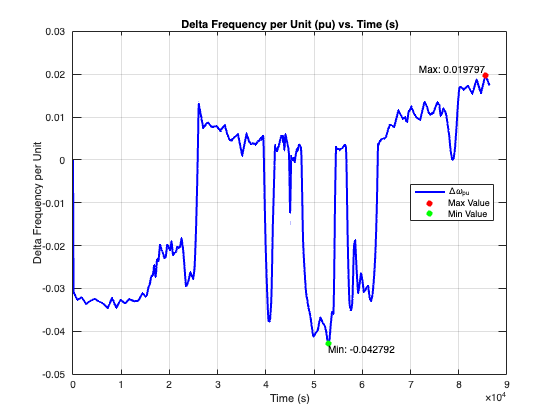

[max_val, max_idx] = max(delta_wpu_non_sctrl);
[min_val, min_idx] = min(delta_wpu_non_sctrl);
figure;
plot(x, delta_wpu_non_sctrl, '-b', 'LineWidth', 2); 
hold on;
scatter(x(max_idx), max_val, 'ro', 'filled', 'DisplayName', 'Maximum');
scatter(x(min_idx), min_val, 'go', 'filled', 'DisplayName', 'Minimum');
text(x(max_idx), max_val, sprintf('Max: %f', max_val), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
text(x(min_idx), min_val, sprintf('Min: %f', min_val), 'VerticalAlignment', 'top', 'HorizontalAlignment', 'left');
ylabel("Delta Frequency per Unit");
ylim([-0.05 0.03]);
xlabel("Time (s)");
title('Delta Frequency per Unit (pu) vs. Time (s)');
legend({'\Delta\omega_{pu}', 'Max Value', 'Min Value'}, 'Location', 'best');
grid on;
hold off;

**- With Secondary Control**

The most simple implementation would be p_es_sec_ref = -K*integral(delta_wpu)*es.P_pe_rated where a large K results in a fast acting secondary loop, and a small K results in a slow loop.  Remember that we want the secondary loop to stabilize the frequency to 60 Hz (delta_wpu = 0) over several minutes.  

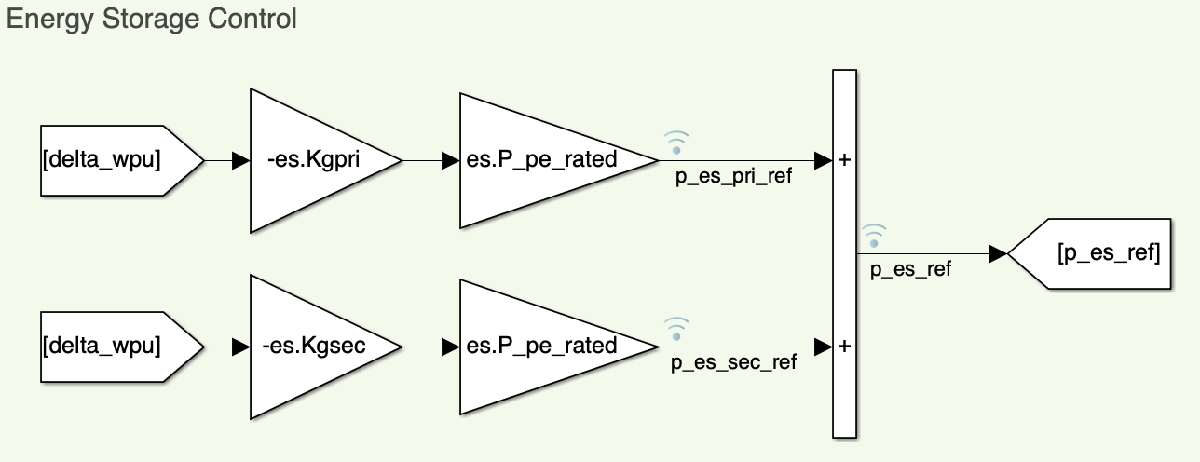

Surprisingly, when the K of secondary control is set to 20/(60*10), it barely affects the delta_wpu, Frequency range is still 61.187757 Hz to 57.432623 Hz. However, when the K is set to 100, the Frequency range is 60.206588 Hz to 59.553478 Hz.

es.Kgsec = es.Kgpri*5;
es.Kgsec

ans = 100

log_with_sctrl = sim("hw_microgrids1_with_sctrl").logsout;
delta_wpu_with_sctrl = log_with_sctrl.getElement("delta_wpu").Values.Data;
x = log_with_sctrl.getElement("delta_wpu").Values.Time;
fprintf("delta_wpu maximum: %f pu, minimum: %f pu", max(delta_wpu_with_sctrl), min(delta_wpu_with_sctrl))

delta_wpu maximum: 0.003443 pu, minimum: -0.007442 pu

fprintf("Frequency range: %f Hz to %f Hz", 60+max(delta_wpu_with_sctrl*60), 60+min(delta_wpu_with_sctrl*60))

Frequency range: 60.206598 Hz to 59.553457 Hz

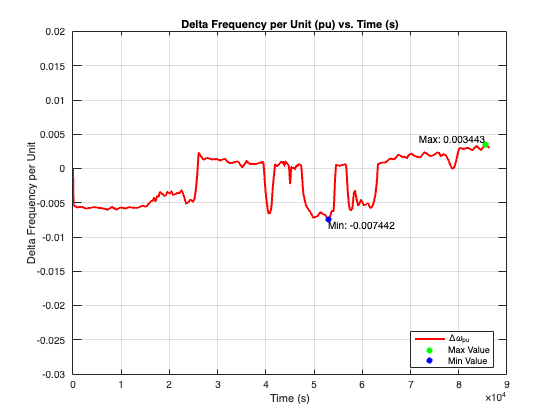

[max_val, max_idx] = max(delta_wpu_with_sctrl);
[min_val, min_idx] = min(delta_wpu_with_sctrl);
figure;
plot(x, delta_wpu_with_sctrl, '-r', 'LineWidth', 2); 
hold on;
scatter(x(max_idx), max_val, 'go', 'filled', 'DisplayName', 'Maximum');
scatter(x(min_idx), min_val, 'bo', 'filled', 'DisplayName', 'Minimum');
text(x(max_idx), max_val, sprintf('Max: %f', max_val), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
text(x(min_idx), min_val, sprintf('Min: %f', min_val), 'VerticalAlignment', 'top', 'HorizontalAlignment', 'left');
ylabel("Delta Frequency per Unit");
ylim([-0.03 0.02]);
xlabel("Time (s)");
title('Delta Frequency per Unit (pu) vs. Time (s)');
legend({'\Delta\omega_{pu}', 'Max Value', 'Min Value'}, 'Location', 'best');
grid on;
hold off;

## Question 4

#### Calculate the Mean Absolute Error in frequency between the two cases (with and without secondary control).  $\textrm{MAE}=\frac{1}{T}\;\int_0^T \left|\Delta \omega_{\textrm{pu}} \right|\;dt$

**- Without Secodary Control**

delta_wpu_non_sctrl_abs = abs(delta_wpu_non_sctrl);
MAE_non_sctrl = trapz(delta_wpu_non_sctrl_abs)*simu.maxStepSize/simu.endTime;
fprintf("MAE without secondary control: %f", MAE_non_sctrl)

MAE without secondary control: 0.018448

**- With Secodary Control**

delta_wpu_with_sctrl_abs = abs(delta_wpu_with_sctrl);
MAE_with_sctrl = trapz(delta_wpu_with_sctrl_abs)*simu.maxStepSize/simu.endTime;
fprintf("MAE with secondary control: %f", MAE_with_sctrl)

MAE with secondary control: 0.003209